# 1D FEM

Authors: Arturo Popoli, Fabio Ragazzi - University of Bologna

## Step 1: minimal working example

*Create an m-function "FEM_1D_s1.m" that solves a general Poisson problem *$\nabla \cdot (p(x) \nabla \varphi) = t(x) $* with the following assumptions*

- *Uniform grid, i.e., *$x_{k+1}-x_{k} = \Delta, \quad \forall k,k+1 $

- *Dirichlet BCs at boundaries*

- *Constant source term *$t(x)=t$

The function call should look something like

*Hints:*

*Consider the general form of the element matrix*


$$K_{el_{k,k+1}} = \left( \matrix{ \int_{\omega_{k,k+1}} p(x)\,\frac{\mathrm{d}\,L_k}{\mathrm{d}\,x}\,\frac{\mathrm{d}\,L_{k}}{\mathrm{d}\,x}\,\mathrm{d}x & \int_{\omega_{k,k+1}} p(x)\,\frac{\mathrm{d}\,L_k}{\mathrm{d}\,x}\,\frac{\mathrm{d}\,L_{k+1}}{\mathrm{d}\,x}\,\mathrm{d}x \cr \int_{\omega_{k,k+1}} p(x)\,\frac{\mathrm{d}\,L_{k+1}}{\mathrm{d}\,x}\,\frac{\mathrm{d}\,L_{k}}{\mathrm{d}\,x}\,\mathrm{d}x & \int_{\omega_{k,k+1}} p(x)\,\frac{\mathrm{d}\,L_{k+1}}{\mathrm{d}\,x}\,\frac{\mathrm{d}\,L_{k+1}}{\mathrm{d}\,x}\,\mathrm{d}x \cr} \right)
$$
 

and the element right-hand-side array:


$$\{s\}_{el_{k,k+1}} = - \left( \matrix{ \int_{\omega_{k,k+1}} L_{k}(x)\,t(x)\,\mathrm{d}x \cr \int_{\omega_{k,k+1}} L_{k+1}(x)\,t(x)\,\mathrm{d}x \cr} \right)$$


For piecewise-linear shape (*hat*) functions, the element matrix simplifies to to:


$$K_{el_{k,k+1}} = \left(\matrix{\frac{1}{\Delta^2} \int_{\omega_{k,k+1}} p(x)\,\mathrm{d}x & -\frac{1}{\Delta^2} \int_{\omega_{k,k+1}} p(x)\,\mathrm{d}x  \cr -\frac{1}{\Delta^2} \int_{\omega_{k,k+1}} p(x)\,\mathrm{d}x  & \frac{1}{\Delta^2} \int_{\omega_{k,k+1}} p(x)\,\mathrm{d}x  \cr} \right)
$$
 

*If p is constant the integrals are trivial and it can be shown (****your job for the reports****) that:*

$K_{el_{k,k+1}} = \left( \matrix{ \frac{p}{\Delta} & -\frac{p}{\Delta} \cr -\frac{p}{\Delta} & \frac{p}{\Delta} \cr} \right)
$, $\{s\}_{el_{k,k+1}} = - \left( \matrix{ t \frac{\Delta}{2} \cr t \frac{\Delta}{2} \cr} \right)$

**Solution**

*Define mesh - uniform spacing *

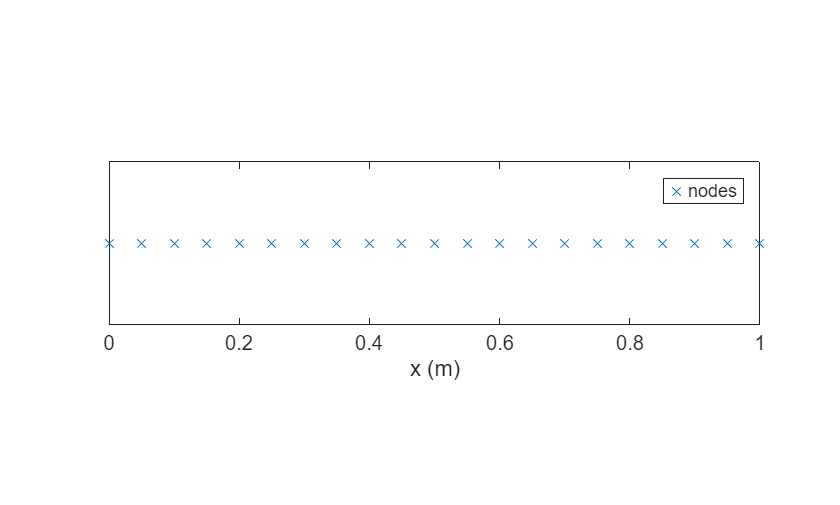

clear variables

n = 21; % number of nodes
L = 1; % domain length

x = linspace(0,L,n); % n equispaced nodes between 0 and 1

plot(x,zeros(n,1),'x'); xlabel('x (m)'); legend('nodes')
yticks([]) % removes y axsis
pbaspect([4 1 1])

*Run the code with *$\varphi_a = 1
$*, *$\varphi_b = 0
$*, *$p = 1$*; *$t = 5$

p = 1;
t = 5;
phi_a = 1;
phi_b = 0;

[phi] = FEM_1D_s1(x,p,t,phi_a,phi_b);

*Plot the solution*

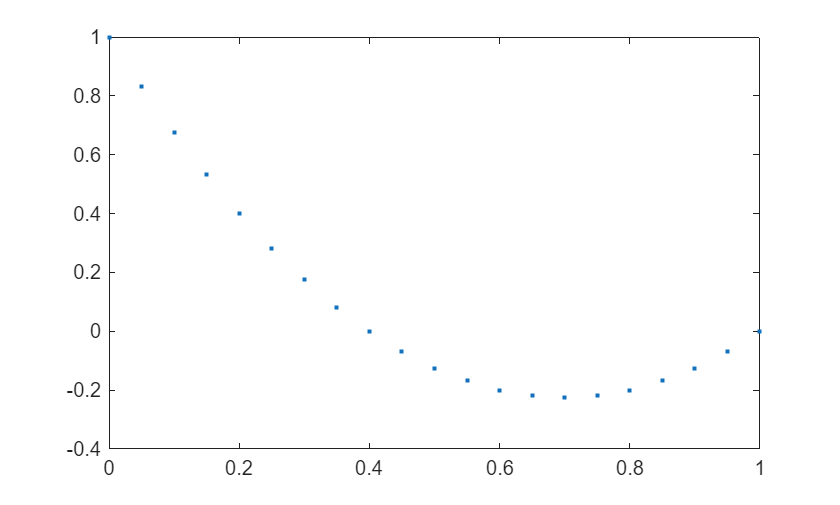

plot(x,phi,'.')

*Check how the solution changes when setting *$$\varphi(a)=0$ $* and, in turn, *$t = 1$*, *$t = 2$

### Step 1.1: check with analytic solution

When $t(x)
$ and $p(x)$ are uniform, i.e., $t(x) = t_0$ and $p(x) = p_0$ (remember this hypothesis!), there exist an analytic solution:


$$    \frac{d^2 \varphi}{dx^2} = \frac{t_0}{p_0}$$



$$    \varphi(x) = \frac{t_0}{2p_0} x^2 + Ax + B$$


where A and B can be determined based on the boundary conditions. 

In the case of Dirichlet-Dirichlet boundary conditions


$$\mathrm{left \ boundary:} \quad \varphi(0) = \varphi_0 \Rightarrow B = \varphi_0$$



$$\mathrm{right \ boundary}: \quad \varphi(L) = \varphi_L \Rightarrow\frac{t_0}{2p_0} L^2 + A L + \varphi_0 = \varphi_L$$


Solve for $A$


$$A = \frac{\varphi_L - \varphi_0 - \frac{t_0}{2p_0} L^2}{L}$$


Analytic solution


$$    \varphi(x) = \frac{t_0}{2p_0} x^2 + \left( \frac{\varphi_L - \varphi_0 - \frac{t_0}{2p_0} L^2}{L} \right)x + \varphi_0$$


**Solution**

*Define analytic solution*

*Plot the analytical solution against the numerical solution, for *$p = 1; phi_a = 1; phi_b = 0; t = 1$

## Step 2: variable spacing

*Create an m-function "FEM_1D_s2.m" that can handle arbitrarily-spaced meshes*

**Solution**

*Define and visualize a stretched mesh. Take inspiration from the following*

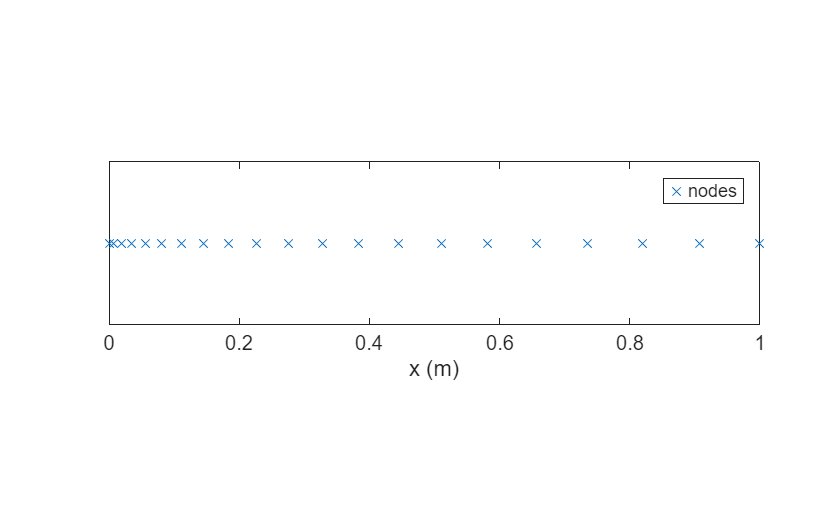

x = linspace(0,L,n); % define uniform mesh
x = x.*linspace(1,10,n);
x = x/10; % rescale to L

plot(x,zeros(n,1),'x'); xlabel('x (m)'); legend('nodes')
yticks([]) % removes y axsis
pbaspect([4 1 1])

*Run the code with *$\varphi_a = 1; \varphi_b = 0; p=1; t = 5$

p = 1;
t = 5;
phi_a = 1;
phi_b = 0;

[phi] = FEM_1D_s2(x,p,t,phi_a,phi_b);

*Compare to analytical solution*

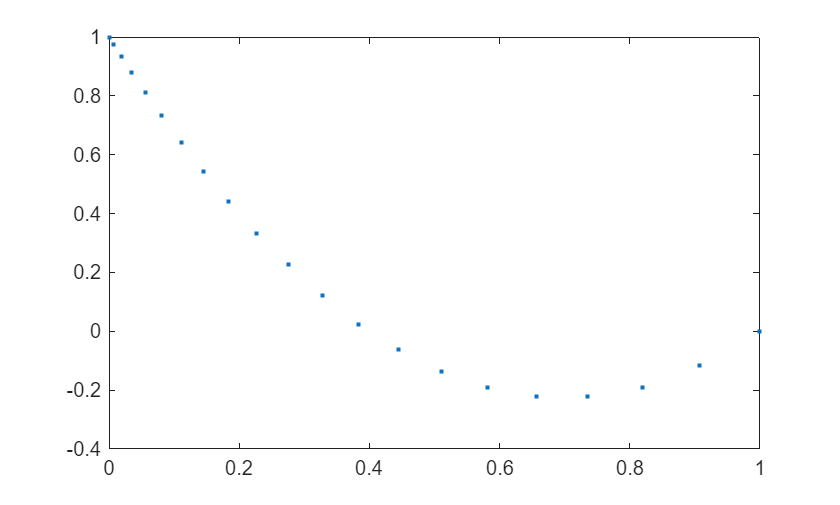

plot(x,phi,'.')

## Step 3: arbitrary coeffients/source terms

*Create an m-function "FEM_1D_s3.m" that can handle arbitrary values of *$p(x)$* and *$t(x)$*.*

*Hints:*

*Because now *$p(x)$* is not constant, we cannot take it out of the integral. Use ****your own Gauss integration function ****to get the element matrix entries:*


$$K_{el_{k,k+1}} = \left(\matrix{\frac{1}{\Delta^2} \int_{\omega_{k,k+1}} p(x)\,\mathrm{d}x & -\frac{1}{\Delta^2} \int_{\omega_{k,k+1}} p(x)\,\mathrm{d}x  \cr -\frac{1}{\Delta^2} \int_{\omega_{k,k+1}} p(x)\,\mathrm{d}x  & \frac{1}{\Delta^2} \int_{\omega_{k,k+1}} p(x)\,\mathrm{d}x  \cr} \right)
$$
 

*...and do the same for right-hand side array entries for *$t(x)$


$$\{s\}_{el_{k,k+1}} = - \left( \matrix{ \int_{\omega_{k,k+1}} L_{k}(x)\,t(x)\,\mathrm{d}x \cr \int_{\omega_{k,k+1}} L_{k+1}(x)\,t(x)\,\mathrm{d}x \cr} \right)$$


**Solution**

*Define a mesh (you can use the stretched mesh from the previous section)*

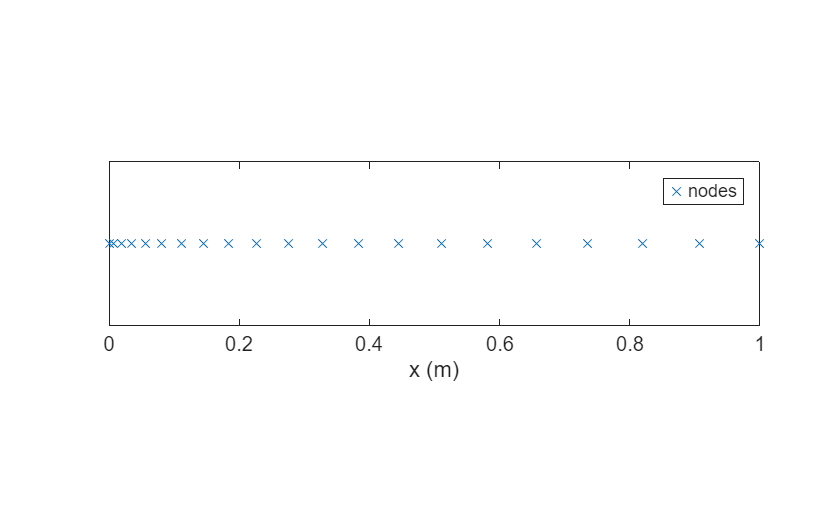

x = linspace(0,L,n); % define uniform mesh
x = x.*linspace(1,10,n);
x = x/10; % rescale to L

plot(x,zeros(n,1),'x'); xlabel('x (m)'); legend('nodes')
yticks([]) % removes y axsis
pbaspect([4 1 1])

Run the code with constant p(x) and t(x). Use:

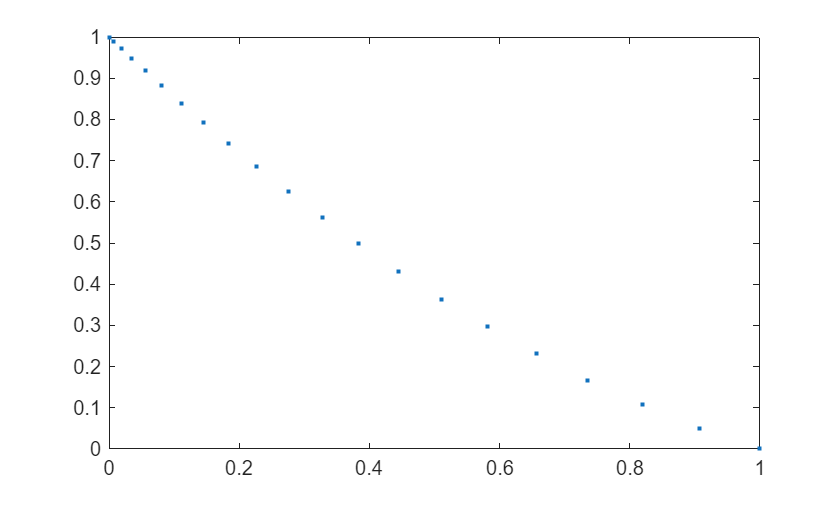

p0 = 1;
t0 = 1;

p = @(x) p0*ones(size(x));
t = @(x) t0*ones(size(x));

[phi] = FEM_1D_s3(x,p,t,phi_a,phi_b);
plot(x,phi,'.')

Now more extreme cases... try

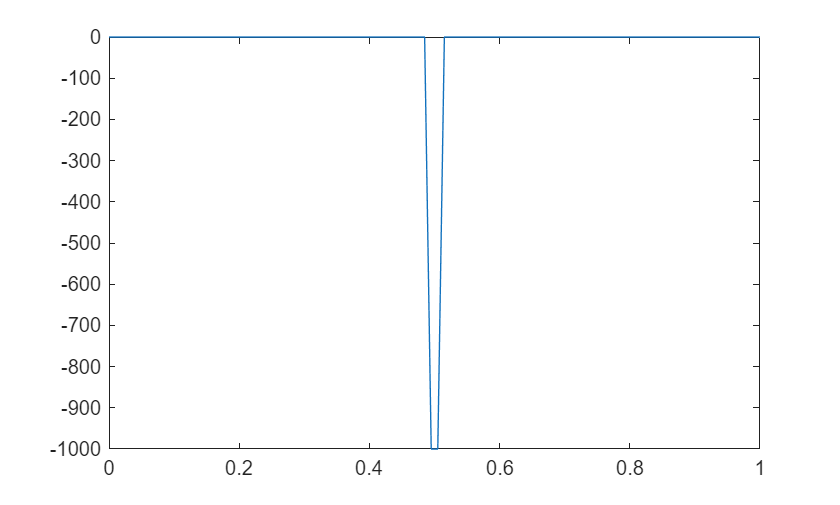

x = linspace(0,L,100); % define uniform mesh
t = @(x) -(x >= 0.49 & x <= 0.51) * 1e3;
plot(x,t(x))

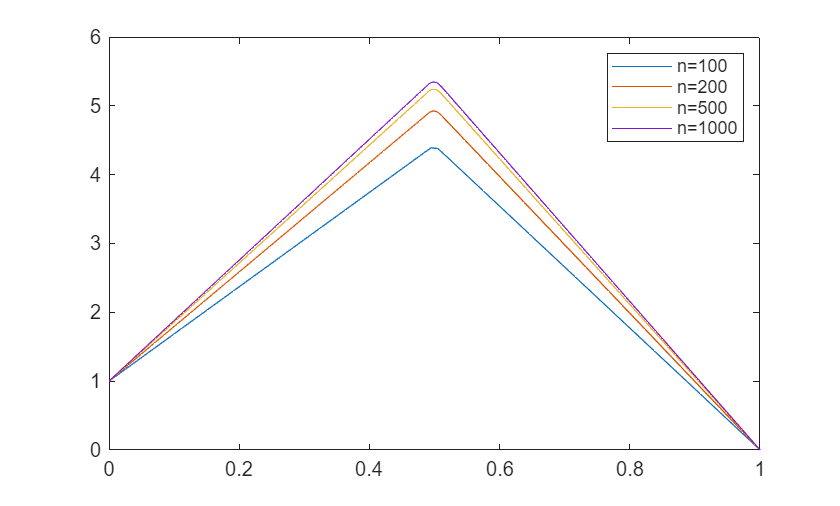


[phi] = FEM_1D_s3(x,p,t,phi_a,phi_b);
plot(x,phi)
hold on
x = linspace(0,L,200);
[phi] = FEM_1D_s3(x,p,t,phi_a,phi_b);
plot(x,phi)

x = linspace(0,L,500);
[phi] = FEM_1D_s3(x,p,t,phi_a,phi_b);
plot(x,phi)

x = linspace(0,L,1000);
[phi] = FEM_1D_s3(x,p,t,phi_a,phi_b);
plot(x,phi)
hold off
legend('n=100','n=200','n=500','n=1000')

## Step 4: support for Neumann BCs

*Create an m-function "FEM_1D_s4.m" that also allows for Neumann BCs.*

**Solution**

*Let's recall how we derived the expression for Neumann BCs. Here is the general weighted residual in weak form:*


$$\int_{\Omega_k} p(x)\,\frac{\mathrm{d}\,L_k}{\mathrm{d}\,x}\,\frac{\mathrm{d}\,\tilde{\varphi}}{\mathrm{d}\,x}\mathrm{d}x = \left[L_k(x)\,p(x)\frac{\mathrm{d}\,\tilde{\varphi}}{\mathrm{d}\,x}\right]_a^b -\int_{\Omega_k} L_k(x)\,t(x)\mathrm{d}x  $$


*We are looking at the boundary in *$x=b$*:*

- *The rightmost support domain has only one element: *$\omega_{n-1,n$

- 
$$L_k(x)=1 \ \mathrm{in} \ x = b $$


*So the expression becomes:*


$$\left[\int_{\omega_{n-1,n}} \frac{\mathrm{d}\,L_n}{\mathrm{d}\,x}\, p(x)\frac{\mathrm{d}\,L_{n-1}}{\mathrm{d}\,x}\mathrm{d}x \right]\,\varphi_{n-1}+
\left[\int_{\omega_{n-1,n}} \frac{\mathrm{d}\,L_n}{\mathrm{d}\,x}\, p(x) \frac{\mathrm{d}\,L_{n}}{\mathrm{d}\,x}\mathrm{d}x \right]\,\varphi_{n} = \\
= \left. p(x_n)\frac{\mathrm{d}\,\tilde{\varphi}}{\mathrm{d}\,x}\right|_{x=x_n} -\int_{\omega_{n-1,n}} L_n(x)\,t(x)\mathrm{d}x  $$


*Note: all the terms except *$ \left. p(x_n)\frac{\mathrm{d}\,\tilde{\varphi}}{\mathrm{d}\,x}\right|_{x=x_n}$* have already been written into [K] and [Rhs] by the element matrix for element *$n-1$*. So you can just add:*

*Run the code and visualize results*

### Step 4.1: check with solution using Dirichlet BCs on full domain

*Compare the Dirichlet-Neumann solution on half domain with a Dirichlet-Diriclet solution on the full domain. Use symmetric zero-Dirichlet BCs*